## `Задание 1. Свободное движение`

mdl = "task_1";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

a0 = 4.5; a1 = 4.5; iy = 1; idy = 0;
out1 = sim(simIn);

a0 = 101.44; a1 = 2.4;
out2 = sim(simIn);

a0 = 100; a1 = 0;
out3 = sim(simIn);

a0 = 101.44; a1 = -2.4; iy = 0.05;
out4 = sim(simIn);

a0 = 4.5; a1 = -4.5;
out5 = sim(simIn);

a0 = -0.64; a1 = 0; iy = 0; idy = 0.1;
out6 = sim(simIn);

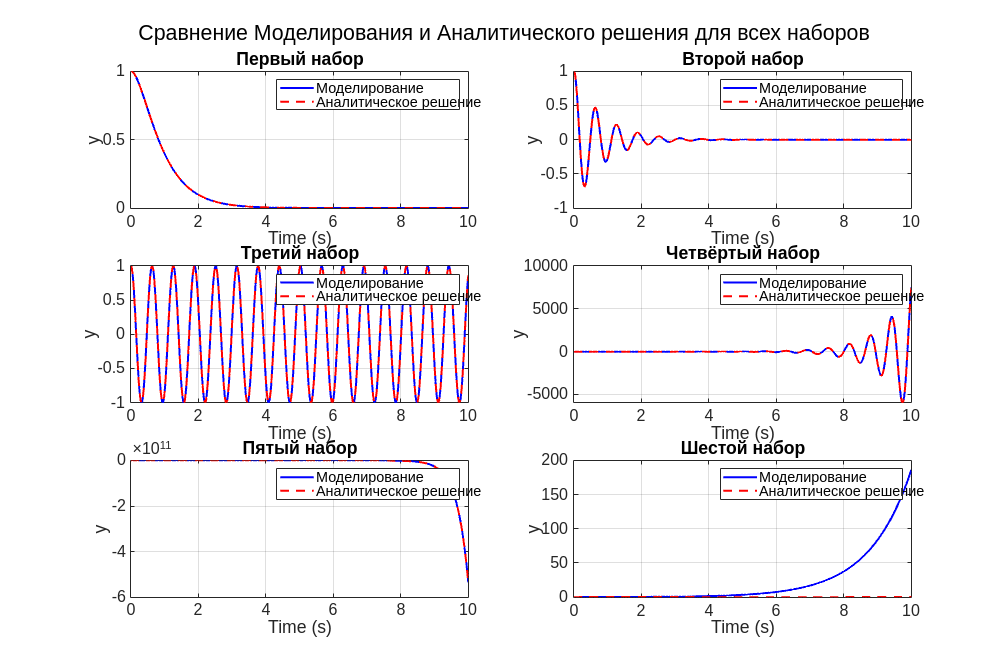

res1 = get(out1, "yout");
res2 = get(out2, "yout");
res3 = get(out3, "yout");
res4 = get(out4, "yout");
res5 = get(out5, "yout");
res6 = get(out6, "yout");

y1 = res1{1}.Values.Data;
y2 = res2{1}.Values.Data;
y3 = res3{1}.Values.Data;
y4 = res4{1}.Values.Data;
y5 = res5{1}.Values.Data;
y6 = res6{1}.Values.Data;

t1 = out1.tout;
t2 = out2.tout;
t3 = out3.tout;
t4 = out4.tout;
t5 = out5.tout;
t6 = out6.tout;

y1a = 2*exp(-1.5*t1) - exp(-3*t1);                     % Formula for y1a
y2a = exp(-1.2*t2).*cos(10*t2) + exp(-1.2*t2).*sin(10*t2)*0.12;  % Formula for y2a
y3a = cos(10*t3);                                      % Formula for y3a
y4a = exp(1.2*t4).*(0.05*cos(10*t4) - 0.006*sin(10*t4)); % Formula for y4a
y5a = -0.05*exp(3*t5) + 0.1*exp(1.5*t5);               % Formula for y5a
y6a = 0.125*sin(0.8*t6);                               % Formula for y6a

% Create a figure
figure;

% Subplot 1: y1 and y1a
subplot(3, 2, 1);
plot(t1, y1, 'b', 'LineWidth', 1.5); hold on;
plot(t1, y1a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Первый набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 2: y2 and y2a
subplot(3, 2, 2);
plot(t2, y2, 'b', 'LineWidth', 1.5); hold on;
plot(t2, y2a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Второй набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 3: y3 and y3a
subplot(3, 2, 3);
plot(t3, y3, 'b', 'LineWidth', 1.5); hold on;
plot(t3, y3a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Третий набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 4: y4 and y4a
subplot(3, 2, 4);
plot(t4, y4, 'b', 'LineWidth', 1.5); hold on;
plot(t4, y4a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Четвёртый набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 5: y5 and y5a
subplot(3, 2, 5);
plot(t5, y5, 'b', 'LineWidth', 1.5); hold on;
plot(t5, y5a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Пятый набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 6: y6 and y6a
subplot(3, 2, 6);
plot(t6, y6, 'b', 'LineWidth', 1.5); hold on;
plot(t6, y6a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Шестой набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Adjust the layout
sgtitle('Сравнение Моделирования и Аналитического решения для всех наборов', 'FontSize', 16); % Super title for all plots
set(gcf, 'Position', [100, 100, 1200, 800]); % Adjust figure size

## Задание 2. Область устойчивости

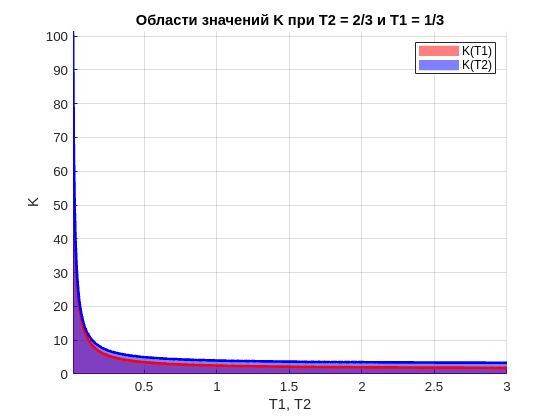

T2 = 2/3;  % Фиксированное значение T2
T1 = 1/3;  % Фиксированное значение T1

% Функция верхней границы K = (T1 + T2) / (T1 * T2)
KT1_max = @(T1) (T1 + T2) ./ (T1 * T2);
KT2_max = @(T2) (T1 + T2) ./ (T1 * T2);

% Диапазон значений T1
T1_min = 0.01;  % Минимум для T1 (чтобы избежать деления на ноль)
T1_max = 3;    % Максимум для T1
T1_values = linspace(T1_min, T1_max, 500);  % Создаем массив значений T1

% Диапазон значений T2
T2_min = 0.01;  % Минимум для T2 (чтобы избежать деления на ноль)
T2_max = 3;    % Максимум для T2
T2_values = linspace(T2_min, T2_max, 500);  % Создаем массив значений T1

% Вычисляем значения K
KT1_values = KT1_max(T1_values);
KT2_values = KT2_max(T2_values);

% Создаем фигуру
figure;
hold on;

% 1. Заполняем область для переменного T1
fill([T1_values, fliplr(T1_values)], [zeros(size(T1_values)), fliplr(KT1_values)], "red",  'FaceAlpha', 0.5, 'EdgeColor', 'none');
fill([T2_values, fliplr(T1_values)], [zeros(size(T2_values)), fliplr(KT2_values)], "blue", 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% 2. Строим линию для верхней границы K(T1)
plot(T1_values, KT1_values, 'r', 'LineWidth', 2);
plot(T2_values, KT2_values, 'b', 'LineWidth', 2);

% Подписи осей
xlabel('T1, T2');
ylabel('K');
title('Области значений K при T2 = 2/3 и T1 = 1/3');
legend("K(T1)", "K(T2)")

% Добавляем сетку
grid on;

% Устанавливаем лимиты осей
xlim([T1_min, T1_max]);
ylim([0, max(K_values)]);

hold off;

mdl = "task_2";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

K = 2; T1 = 1/3;T2 = 0.1;
out21 = sim(simIn);

K = 4; T1 = 1/3; T2 = 1;
out22 = sim(simIn);

K = 10; T1 = 1/3; T2 = 1;
out23 = sim(simIn);

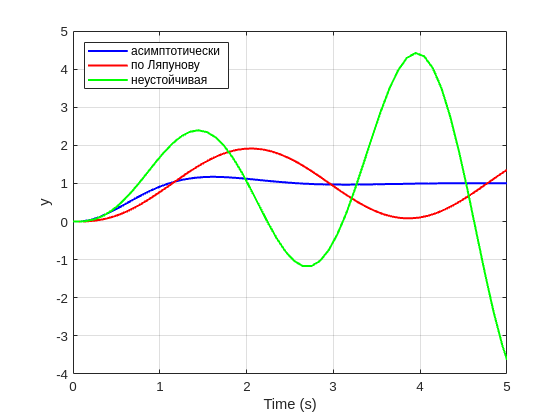

res1 = get(out21, "yout");
res2 = get(out22, "yout");
res3 = get(out23, "yout");

y1 = res1{1};
y2 = res2{1};
y3 = res3{1};

% Получение времени симуляции
t1 = out21.tout;
t2 = out22.tout;
t3 = out23.tout;

% Построение графика с двумя сабплотами
figure;
 
plot(t1, y1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t2, y2.Values.Data, 'r-', 'LineWidth', 1.5);
plot(t3, y3.Values.Data, 'g-', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('y');
legend('асимптотически', 'по Ляпунову', 'неустойчивая', 'Location', 'northwest');
hold off;

## Задание 3. Автономный генератор

mdl = "task_3";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out3 = sim(simIn);

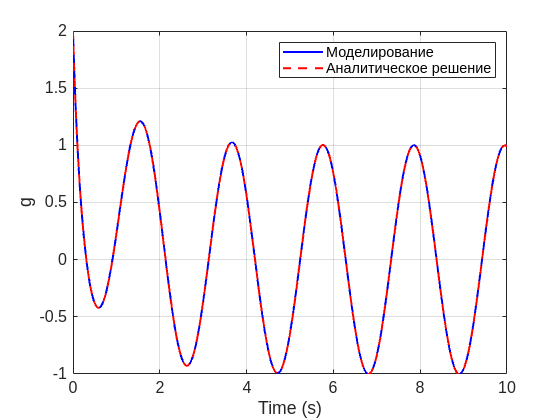

res = get(out3, "yout");

t = out3.tout;
g = res{1}.Values.Data;
ga = sin(-3*t) + exp(-9*t) + exp(-t);

figure;

plot(t, g, 'b', 'LineWidth', 1.5); hold on;
plot(t, ga, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('g');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);